# Example: Case of a diamond geometry

## Define the sampling frequency and simulation duration

clearvars;close all;clc;
addpath('./functions')
fs = 4; % sampling frequency (in Hertz) (10)
Nt = 14; % Nt is the power of 2: If M = 10, 2^M = 1024 time step (15)
[t,f] = getSamplingPara(Nt,fs); % get time and frequency vector

Duration of target time series is 1.14 hours, i.e. 4.1e+03 sec 



Nmax=numel(t); % number of time step (should be equal to 2^M)
Nfreq = numel(f); % number of frequency step (should be equal to 2^(M-1))
dt = median(diff(t)); % time step (should be equal to 1/fs)

## Define the vertices and elements of the geometry

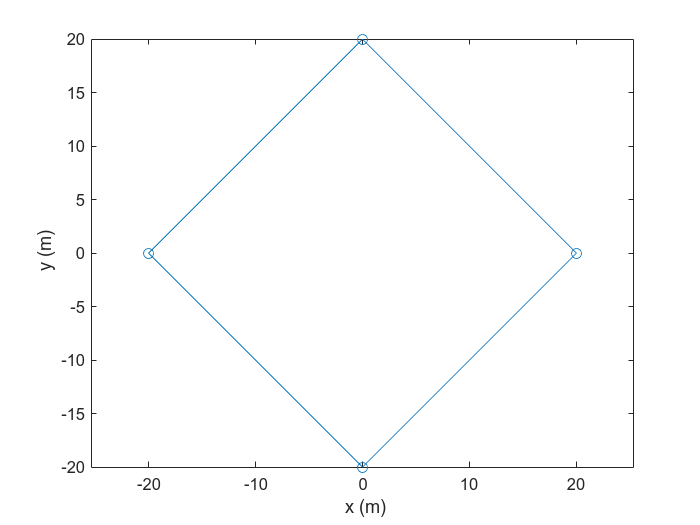

x = [0 20 0 -20 0];  % x-coordinates of the vertices
y = [20 0 -20 0 20]; % y-coordinates of the vertices
zref = 50; % reference height
L=max(max(sqrt(x(:).^2+y(:)'.^2))); % length of the elements

% Nodes
geometry.node.X = x; % must be [1 x M]
geometry.node.Y = y; % must be [1 x M]
geometry.node.Z = zref*ones(1,numel(geometry.node.X));

% elements whose coordinates are at midpoint between the elements
geometry.element.X =  (geometry.node.X(2:end)+geometry.node.X(1:end-1))/2;
geometry.element.Y = (geometry.node.Y(2:end)+geometry.node.Y(1:end-1))/2;
geometry.element.Z = (geometry.node.Z(2:end)+geometry.node.Z(1:end-1))/2;

Nyy = numel(geometry.element.X); % number of element is parametrized by Nyy


plot(geometry.node.X,geometry.node.Y,'o-')
axis equal
xlabel(' x (m)')
ylabel(' y (m)')

## Define the root-coherence parameters

The modified Davenport mode [1]l is the default model here. It is possible to use the modified Bown model too [2]

%  the (x,y,z) coordinate system is not the same as (X,Y,Z)!
clear CoeffDecay
CoeffDecay.Cux = [1 0]; % Modified Davenport model
CoeffDecay.Cuy = [8,  0.01]; % Modified Davenport model
CoeffDecay.Cuz = [11, 0.03]; % Modified Davenport model

CoeffDecay.Cvx = [1 0]; % Modified Davenport model
CoeffDecay.Cvy = [4 0.01]; % Modified Davenport model
CoeffDecay.Cvz = [6, 0.3]; % Modified Davenport model

CoeffDecay.Cwx = [1 0]; % Modified Davenport model
CoeffDecay.Cwy = [5, 0.4]; % Modified Davenport model
CoeffDecay.Cwz = [4, 0.2]; % Modified Davenport model


## Define the wind velocity parameters

clc;clf;close all;
%%%%%%%%%%%%%%%%%%%%%%
kappa = 0.4; % von Karman constant
z0 = 0.05; % roughness height
coeffU = 118; % Coeff for Su
coeffV = 24; % Coeff for Sv
coeffW = 3.6; % Coeff for Sw
coeffUW = 12; % Coeff for Suw
% windDirection = repmat(0,1,M); % Wind direction (non-uniform value)
windDirection = 0; % Wind direction (uniform value)
Uref = 24; % Reference mean wind speed at zref
Nsamples = 10; % Number of realization at each reference wind speed
%%%%%%%%%%%%%%%%%%%%%%


## Get the target mean wind speed profile and one-point spectra

% Get the surface friction velocity from the logarithmic profile
u_star0 =  kappa*Uref./log(zref/z0);
meanU = u_star0./kappa.*log(geometry.element.Z/z0); % Mean wind speed estimated with the logarithmic profile
% Get the one-point PSD at each integration point
[Su,Sv,Sw,Suw] = getTargetSpectra(meanU,u_star0,geometry,f,coeffU,coeffV,coeffW,coeffUW);


fprintf([' Duration = ',char(string(round(minutes(duration(seconds(t(end))))))), ' minutes',...
'\n min(Uref) = ',num2str(min(Uref)), ' m/s',...
'\n max(Uref) = ',num2str(max(Uref)), ' m/s',...
'\n Numel(Uref) = ',num2str(numel(Uref)),...
'\n Num. time step = ',num2str(Nmax),...
'\n fs = ',num2str(fs), ' Hz ',...
'\n zref = ',num2str(zref), ' m ',...
'\n z0 = ',num2str(z0), ' m ',...
'\n coeffU = ',num2str(coeffU),'  ',...
'\n coeffV = ',num2str(coeffV), ' ',...
'\n coeffW = ',num2str(coeffW), ' ',...
'\n coeffUW = ',num2str(coeffUW), ' ',...
'\n Target friction velocity = ',num2str(u_star0,3), ' m/s',...
'\n Nsamples = ',num2str(Nsamples), ' '])

 Duration = 68 minutes
 min(Uref) = 24 m/s
 max(Uref) = 24 m/s
 Numel(Uref) = 1
 Num. time step = 16384
 fs = 4 Hz 
 zref = 50 m 
 z0 = 0.05 m 
 coeffU = 118  
 coeffV = 24 
 coeffW = 3.6 
 coeffUW = 12 
 Target friction velocity = 1.39 m/s
 Nsamples = 10 

## Main loop

rng(10)

vx = nan(Nmax,Nyy,Nsamples);
vy = nan(Nmax,Nyy,Nsamples);
u = nan(Nmax,Nyy,Nsamples);
v = nan(Nmax,Nyy,Nsamples);
w = nan(Nmax,Nyy,Nsamples);

for jj=1:Nsamples
    tic
    [u0,v0,w0,t,dx,dy,N] = windSim4D(f,Su,Sv,Sw,CoeffDecay,meanU,geometry,windDirection,'Suw',Suw);
    u0 = bsxfun(@plus,u0,meanU);
    u(1:N,:,jj) = u0;
    v(1:N,:,jj) = v0;
    w(1:N,:,jj)  = w0;
    [vx0,vy0] = WindToBridgeBase(u0,v0,windDirection,geometry.node.X,geometry.node.Y);
    vx(1:N,:,jj)  = sign(mean(vx0(:))).*vx0;
    vy(1:N,:,jj)  = sign(mean(vy0(:))).*vy0;
    
    toc
end

Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.300661 seconds.


Elapsed time is 0.523850 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.261993 seconds.


Elapsed time is 0.271989 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.271478 seconds.


Elapsed time is 0.291119 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.236974 seconds.


Elapsed time is 0.250541 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.282897 seconds.


Elapsed time is 0.303777 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.250183 seconds.


Elapsed time is 0.261821 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.243286 seconds.


Elapsed time is 0.259921 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.237045 seconds.


Elapsed time is 0.247124 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.217873 seconds.


Elapsed time is 0.228582 seconds.


Element no 1 is the first impacted by the wind from 0 degrees 
Elapsed time is 0.271158 seconds.


Elapsed time is 0.288776 seconds.



% Remove the time steps that are outside the time scale of the first point
% impacted by the gust
u(N+1:end,:,:)=[];
v(N+1:end,:,:)=[];
w(N+1:end,:,:)=[];
vx(N+1:end,:,:)=[];
vy(N+1:end,:,:)=[];   
    
meanVx = abs(mean(vx));

windDataName = ['windData.mat'];
save(windDataName,'vx','vy','w','u','v','t','Uref','meanVx','Su','Sv','Sw','CoeffDecay','geometry','f','windDirection')


## Compute some integral flow characteristics

US = zeros(Nyy,Nsamples);
stdU = zeros(Nyy,Nsamples);
stdV = zeros(Nyy,Nsamples);
stdW = zeros(Nyy,Nsamples);

for ii=1:Nyy
    for jj=1:Nsamples
        US(ii,jj) = frictionVelocity(u(:,ii,jj),v(:,ii,jj),w(:,ii,jj));
        stdU(ii,jj) = nanstd(nandetrend(u(:,ii,jj)));
        stdV(ii,jj) = nanstd(nandetrend(v(:,ii,jj)));
        stdW(ii,jj) = nanstd(nandetrend(w(:,ii,jj)));
    end
end

fprintf(['\n -----------------------------------------------------------------',...
'\n The computed friction velocity is ',num2str(median(US(:)),3),' m/s ',...
'\n Iu =  ',num2str(median(stdU(:))/mean(u(:)),3),...
'\n Iv/Iu =  ',num2str(median(stdV(:))/median(stdU(:)),3),...
'\n Iw/Iu =  ',num2str(median(stdW(:))/median(stdU(:)),3),...
'\n stdU/u_star =  ',num2str(median(stdU(:))/median(US(:)),3),...
'\n stdV/u_star =  ',num2str(median(stdV(:))/median(US(:)),3),...
'\n stdW/u_star =  ',num2str(median(stdW(:))/median(US(:)),3),...
'\n ',windDataName,' is saved ',...
'\n ----------------------------------------------------------------- \n\n'])


 -----------------------------------------------------------------
 The computed friction velocity is 1.38 m/s 
 Iu =  0.124
 Iv/Iu =  0.784
 Iw/Iu =  0.604
 stdU/u_star =  2.16
 stdV/u_star =  1.69
 stdW/u_star =  1.31
 windData.mat is saved 
 ----------------------------------------------------------------- 



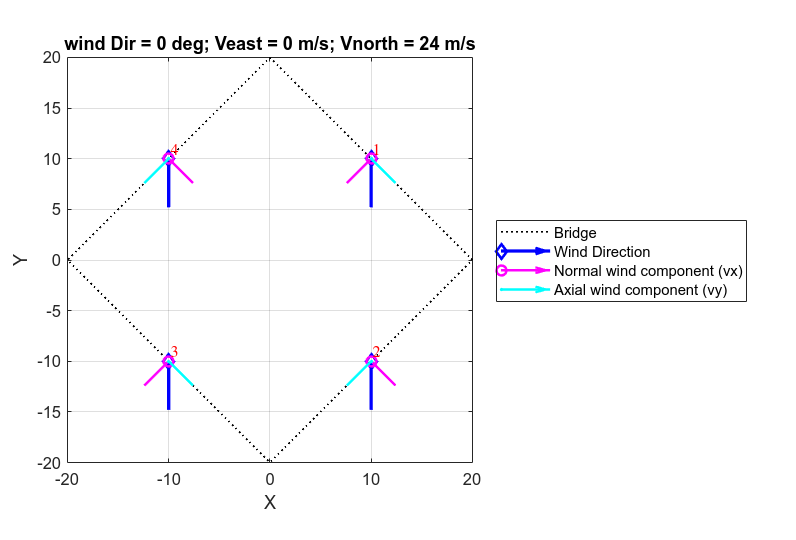

clf;close all;
figure('position',[738   103   685   465])
PlotWindProjection(geometry,meanU,vx0,vy0,windDirection)
axis equal

## Time series visualization

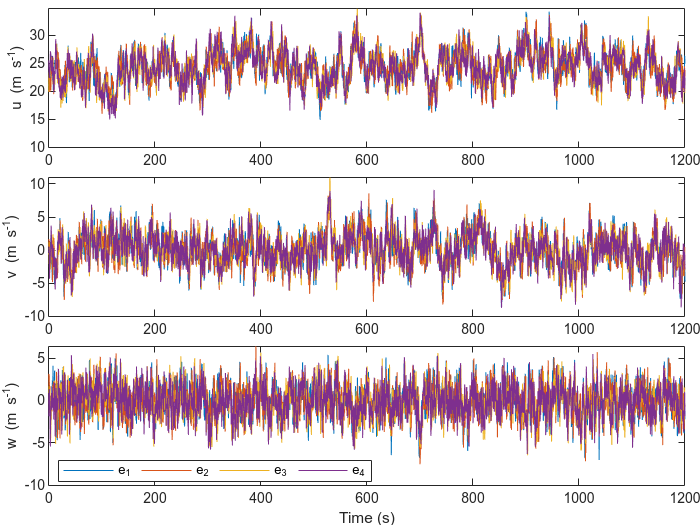

clf;close all;
figure
tiledlayout(3,1,"TileSpacing","tight","Padding","tight")
nexttile
plot(t,u(:,:,1));
ylabel('u (m s^{-1})')
xlim([0 1200])
nexttile
plot(t,v(:,:,1));
ylabel('v (m s^{-1})')
xlim([0 1200])
nexttile
plot(t,w(:,:,1));
ylabel('w (m s^{-1})')
xlim([0 1200])
xlabel('Time (s)')
set(gcf,'color','w')
legend('e_1','e_2','e_3','e_4','location','best','orientation','horizontal')

## Target vs Computed power spectral densities

Elapsed time is 0.059164 seconds.
Elapsed time is 0.039097 seconds.
Elapsed time is 0.048475 seconds.
Elapsed time is 0.040836 seconds.
Elapsed time is 0.031041 seconds.
Elapsed time is 0.033149 seconds.
Elapsed time is 0.034379 seconds.
Elapsed time is 0.048380 seconds.
Elapsed time is 0.051559 seconds.
Elapsed time is 0.048402 seconds.


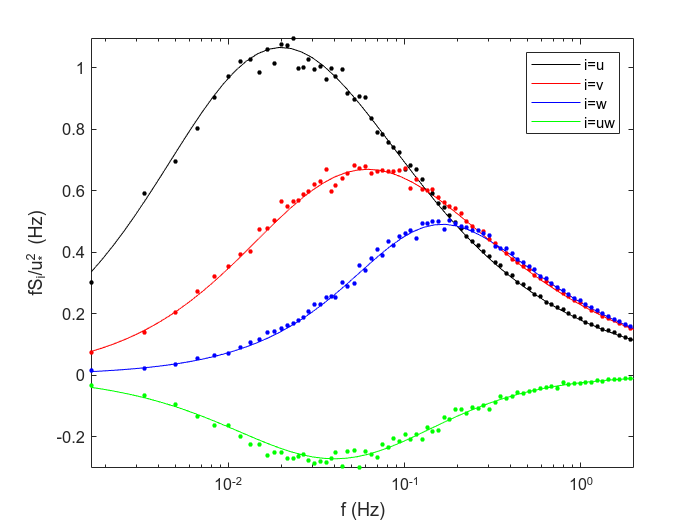

plotSpectra(meanU,u,v,w,fs,t,median(US(:)),geometry,coeffU,coeffV,coeffW,coeffUW)

## Coherence

%% Coherence

Nyy = numel(geometry.element.Y);
Nsamples = size(u,3);
dt=median(diff(t));
fs  = 1/dt;
Nmax=numel(t);
tmax = t(end);
Nfft = round(Nmax./(tmax/180));

if mod(Nfft,2)==0
    cohU = zeros(Nyy,Nyy,Nfft/2+1,Nsamples);
    cohV = zeros(Nyy,Nyy,Nfft/2+1,Nsamples);
    cohW = zeros(Nyy,Nyy,round(Nfft/2)+1,Nsamples);
    cohUW = zeros(Nyy,Nyy,Nfft/2+1,Nsamples);
    quadCohU = zeros(Nyy,Nyy,Nfft/2+1,Nsamples);
    quadCohV = zeros(Nyy,Nyy,round(Nfft/2)+1,Nsamples);
    quadCohW = zeros(Nyy,Nyy,round(Nfft/2)+1,Nsamples);
    quadCohUW = zeros(Nyy,Nyy,round(Nfft/2)+1,Nsamples);
    
else
    cohU = zeros(Nyy,Nyy,round(Nfft/2),Nsamples);
    cohV = zeros(Nyy,Nyy,round(Nfft/2),Nsamples);
    cohW = zeros(Nyy,Nyy,round(Nfft/2),Nsamples);
    cohUW = zeros(Nyy,Nyy,round(Nfft/2),Nsamples);
    quadCohU = zeros(Nyy,Nyy,round(Nfft/2),Nsamples);
    quadCohV = zeros(Nyy,Nyy,round(Nfft/2),Nsamples);
    quadCohW = zeros(Nyy,Nyy,round(Nfft/2),Nsamples);
    quadCohUW = zeros(Nyy,Nyy,round(Nfft/2),Nsamples);
    
end


for indSample= 1:Nsamples
    tic
    for ii=1:Nyy
        for jj=1:Nyy
            [cohU(ii,jj,:,indSample),quadCohU(ii,jj,:,indSample),~] = coherence(detrend(squeeze(u(:,ii,indSample))),detrend(u(:,jj,indSample)),Nfft,round(Nfft/2),Nfft,fs);
            [cohV(ii,jj,:,indSample),quadCohV(ii,jj,:,indSample),~] = coherence(detrend(squeeze(v(:,ii,indSample))),detrend(v(:,jj,indSample)),Nfft,round(Nfft/2),Nfft,fs);
            [cohW(ii,jj,:,indSample),quadCohW(ii,jj,:,indSample),~] = coherence(detrend(squeeze(w(:,ii,indSample))),detrend(w(:,jj,indSample)),Nfft,round(Nfft/2),Nfft,fs);
            [cohUW(ii,jj,:,indSample),quadCohUW(ii,jj,:,indSample),freq] = coherence(detrend(squeeze(w(:,ii,indSample))),detrend(u(:,jj,indSample)),Nfft,round(Nfft/2),Nfft,fs);
        end
    end
    toc
end

Elapsed time is 5.780915 seconds.
Elapsed time is 5.770329 seconds.
Elapsed time is 5.619776 seconds.
Elapsed time is 5.907722 seconds.
Elapsed time is 8.985053 seconds.
Elapsed time is 5.779070 seconds.
Elapsed time is 8.791836 seconds.
Elapsed time is 9.919048 seconds.
Elapsed time is 7.199215 seconds.
Elapsed time is 6.385013 seconds.




cohU1 = squeeze(median(cohU(1,2,:,:),4));
cohW1 = squeeze(median(cohW(1,2,:,:),4));
cohUW1 = squeeze(median(cohUW(1,2,:,:),4));

## Plot the co-coherence

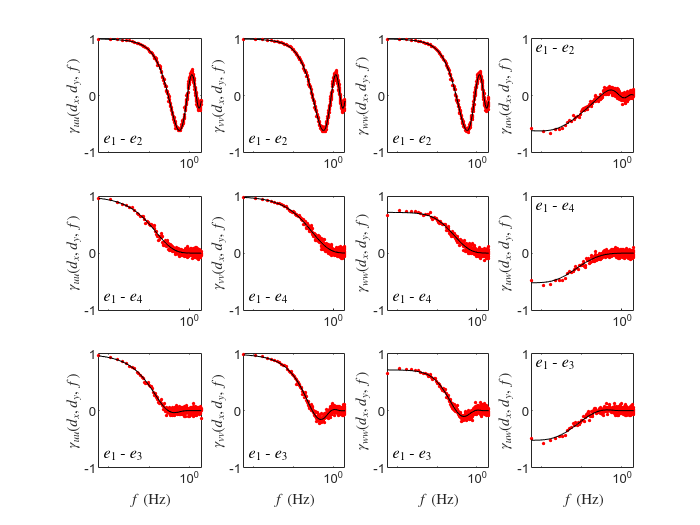


f1 = logspace(log10(freq(2)),log10(freq(end)),100);

Z = geometry.element.Z;
dz = abs(bsxfun(@minus,Z(:)',Z(:)));
meanUcoh = 0.5*abs(bsxfun(@plus,meanU(:)',meanU(:)));
meanZ = 0.5*abs(bsxfun(@plus,geometry.element.Z(:)',geometry.element.Z(:)));

clf;close all;
figure
ind1 = 1;
ind2 = 2;
rowNum = 1;
plotCoh_diamond(freq,f1,meanUcoh,CoeffDecay,cohU,cohV,cohW,...
    cohUW,ind1,ind2,dx,dy,dz,u_star0,geometry,coeffU,coeffV,coeffW,coeffUW,rowNum)
rowNum = 5;
ind1 = 1;
ind2 = 4;
plotCoh_diamond(freq,f1,meanUcoh,CoeffDecay,cohU,cohV,cohW,...
    cohUW,ind1,ind2,dx,dy,dz,u_star0,geometry,coeffU,coeffV,coeffW,coeffUW,rowNum)
rowNum = 9;
ind1 = 1;
ind2 = 3;
plotCoh_diamond(freq,f1,meanUcoh,CoeffDecay,cohU,cohV,cohW,...
    cohUW,ind1,ind2,dx,dy,dz,u_star0,geometry,coeffU,coeffV,coeffW,coeffUW,rowNum)

## Plot the quad-coherence

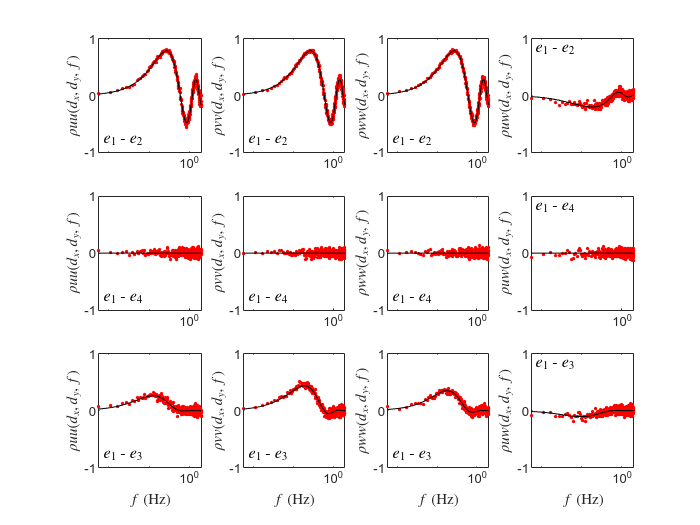

clf;close all;
figure
ind1 = 1;
ind2 = 2;
rowNum = 1;
plotQuadCoh_diamond(freq,f1,meanUcoh,CoeffDecay,quadCohU,quadCohV,quadCohW,...
    quadCohUW,ind1,ind2,dx,dy,dz,u_star0,geometry,coeffU,coeffV,coeffW,coeffUW,rowNum)
rowNum = 5;
ind1 = 1;
ind2 = 4;
plotQuadCoh_diamond(freq,f1,meanUcoh,CoeffDecay,quadCohU,quadCohV,quadCohW,...
    quadCohUW,ind1,ind2,dx,dy,dz,u_star0,geometry,coeffU,coeffV,coeffW,coeffUW,rowNum)
rowNum = 9;
ind1 = 1;
ind2 = 3;
plotQuadCoh_diamond(freq,f1,meanUcoh,CoeffDecay,quadCohU,quadCohV,quadCohW,...
    quadCohUW,ind1,ind2,dx,dy,dz,u_star0,geometry,coeffU,coeffV,coeffW,coeffUW,rowNum)